folder_name = 'truncated_2'

folder_name = 'truncated_2'


p = 'orig';
file = strcat('data\', folder_name, '\',p,'Pc.csv')

file = 'data\truncated_2\origPc.csv'

table = readtable(file);

table = sortrows(table,1);

x = table.Var1;
y = table.Var2;
z = table.Var3;
u = table.Var4;
v = table.Var5;
w = table.Var6;

## Run through matched filter

mf_outputs = zeros(size(table,1), 1);

template = [0 0 1];
template = template/norm(template);
length_template = length(template);

for i=1:size(table,1)
    signal = [u(i) v(i) w(i)];

    length_signal = length(signal);
%    length_convolution = length_signal + length_template - 1;
    
    mf_output = dot(signal, template);
    
%     for I = 1:length_signal
%         mf_output(I) = 0;
%     end
%     
%     for I = 1:length_signal
%         for J = 1:length_template
%             mf_output(I + J) = mf_output(I + J) + (signal(I) * template(J));
%         end
%     end

    mf_outputs(i) = mf_output;
end

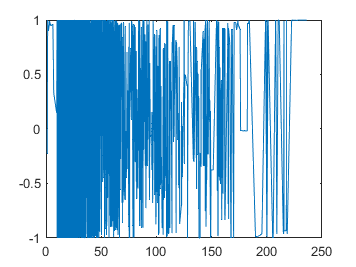

plot(x,mf_outputs)
temp_str = string(template);
saveas(gcf, strcat('figures\', folder_name, '\mf_outputs_',p,'_', ...
    temp_str(1),'_',temp_str(2),'_',temp_str(3),'.png'));

writematrix(mf_outputs,strcat('data\', folder_name, '\mf_outputs_',p,'_', ...
    temp_str(1),'_',temp_str(2),'_',temp_str(3),'.csv'));